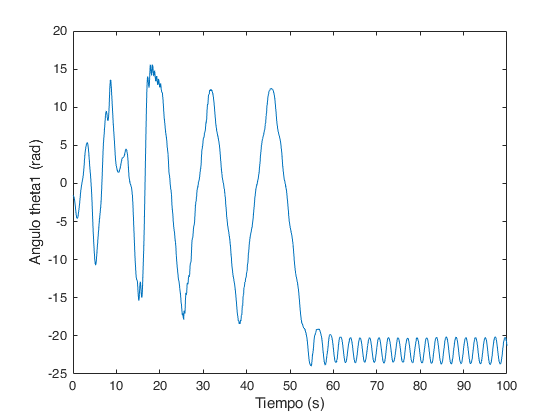

%------------------- Parametros del modelo de un brazo robotico -------------------
m1 = 1; % Masa primera rama del brazo
m2 = 1; % Masa segunda rama del brazo
l1 = 1; % Longitud primera rama del brazo
l2 = 1; % Longitud segunda rama del brazo
parametros = [m1;m2;l1;l2];
u = [1; 1]; % Vector de torques de entrada
% ------------------- Simulacion --------------------------
tiempo = 0:0.1:100; % Se define un tiempo
x0 = [-pi/2;pi/2;0;0]; % Condiciones iniciales para vector de estados
[t,x] = ode45(@(t,x) funcF(t,x,u,parametros),tiempo,x0); % Se simula al brazo robotico
y = funcG(x,parametros); % Se reciben las salidas del sistema

plot(t, y(:,1)); % Se grafica el angulo theta1
xlabel('Tiempo (s)');
ylabel('Angulo theta1 (rad)');

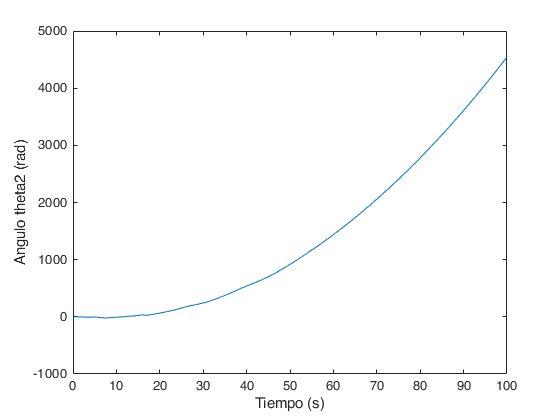

plot(t, y(:,2)); % Se grafica el angulo theta2
xlabel('Tiempo (s)');
ylabel('Angulo theta2 (rad)');